# L06_examples_2

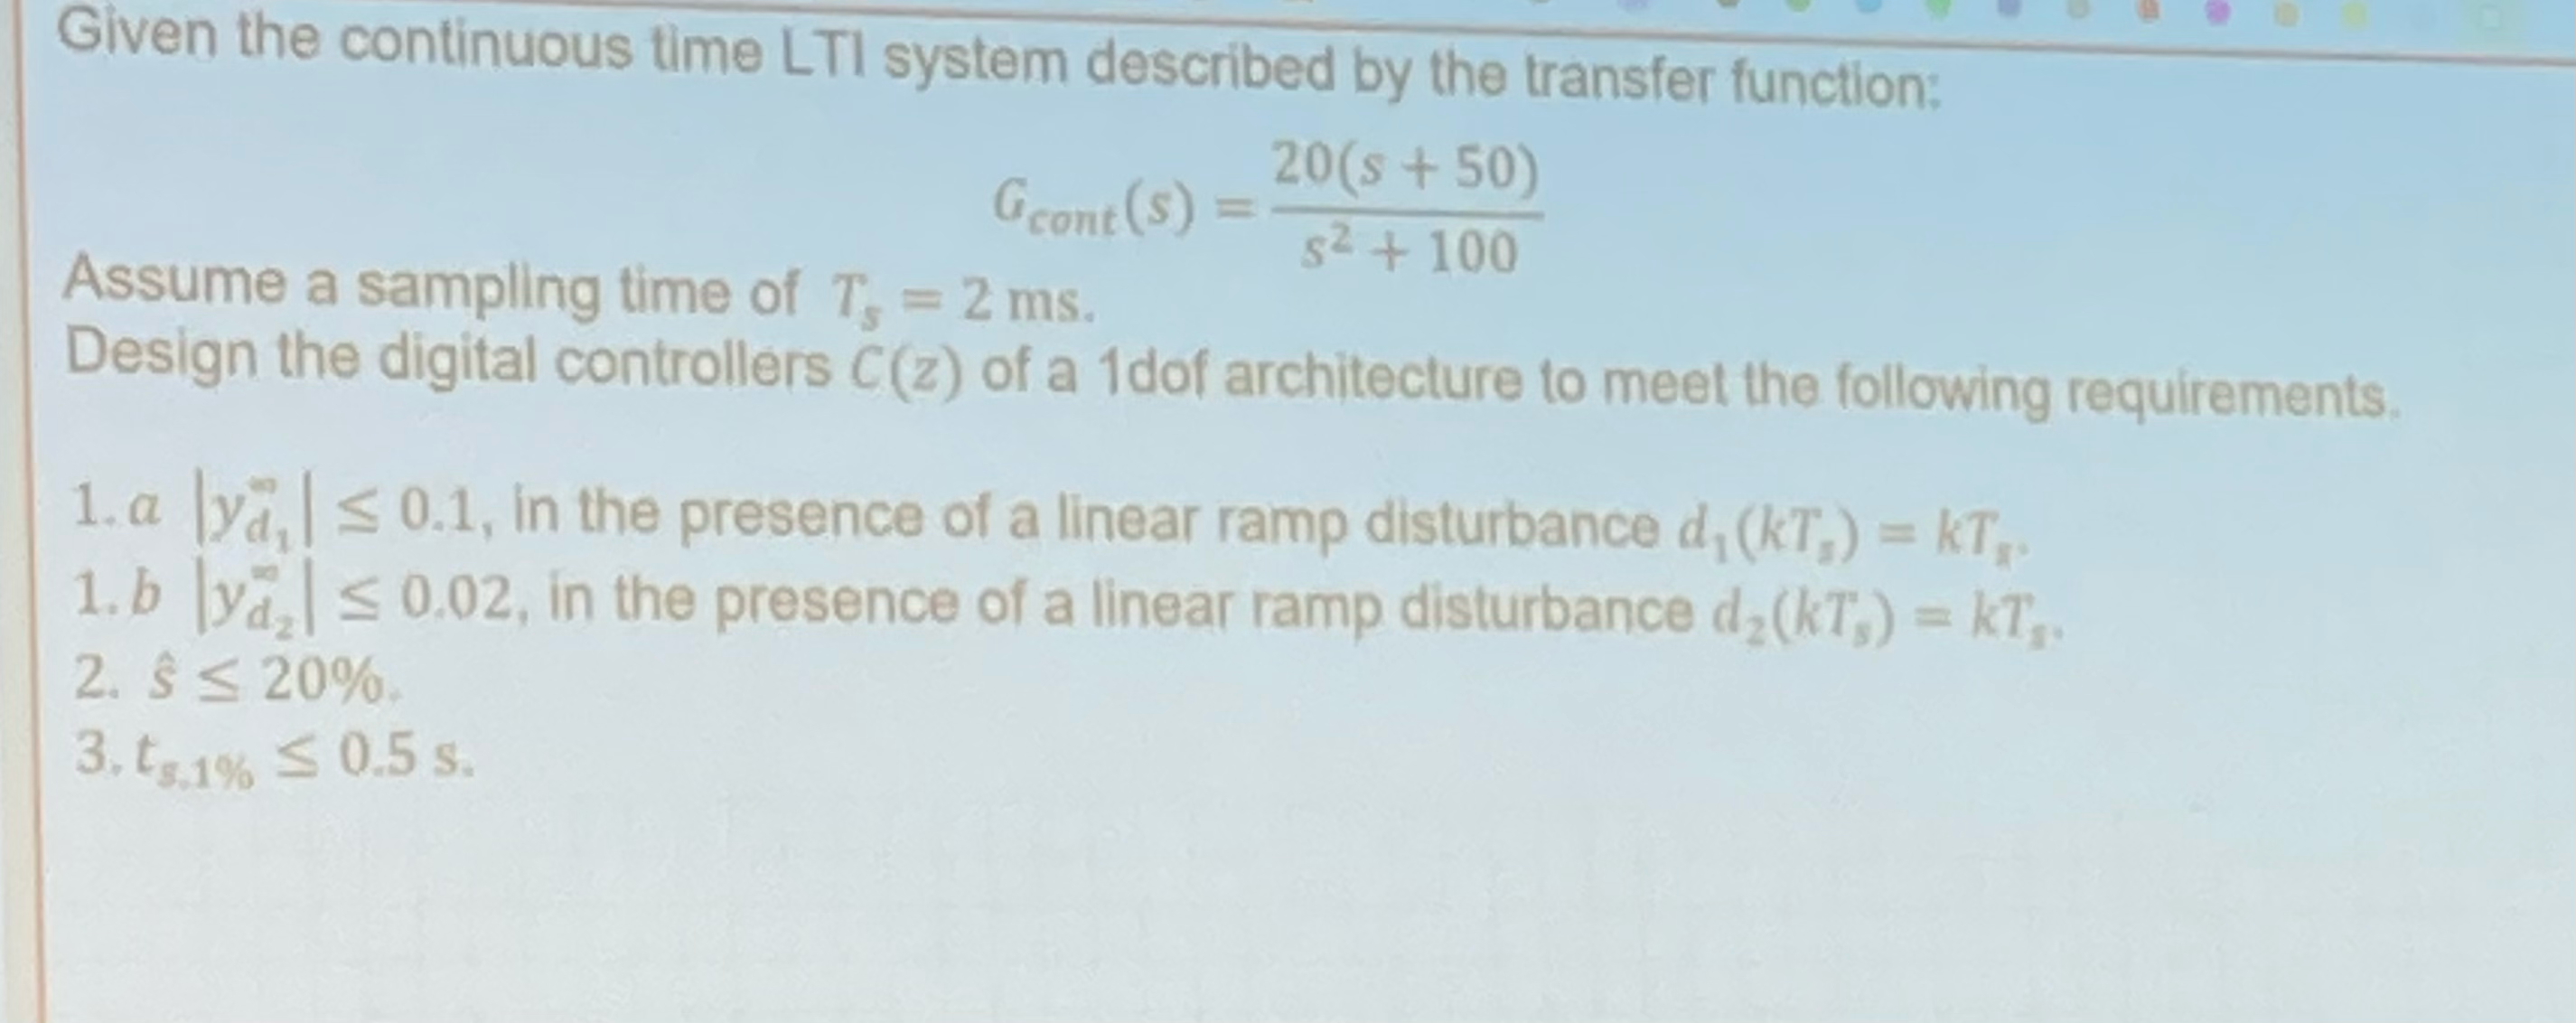

close all
clear
clc

s = tf('s');
G_ct = 20*(s+50)/(s^2+100);
Ts = 2e-3;
G = zpk(c2d(G_ct, Ts, 'zoh'))


G =
 
  0.041997 (z-0.9048)
  -------------------
    (z^2 - 2z + 1)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.


Critical aspect: the denominator has the shape of a perfect square, but we have obtained it by discretization of a CT tf. In CT the correspondant poles (that in DT are in 0) are in 1, but if I look at G I don't see 2 poles in 0, but 2 complex roots. **I must be careful of what I have, because otherwise I will have problems on specifications.** (for example, let's look at 1.B requirement -> if I blindly look at this result I can say that "the specification is already satisfied since I have 2 poles in 1"). So, let's analyze the characteristic of the poles of the CT tf -> I have a couple of purely immaginary poles. According to what we studied, for the sampling transformation, where are mapped imaginary poles into the complex plane? -> In the unit circle (in CT I have the vertical axis, in DT the unitary circle).

zpk statement is an approximation of what I get in reality

So, I have to compute the detailed properties of the tf. In order to do this, I use zpkdata

[zG, pG, kG] = zpkdata(G, 'v');
B = kG*[1 -zG];
A = conv([1 -pG(1)],[1 -pG(2)]);

### Steady state analysis

l1 = 0;

Let's analyse the first requirement. Since the disturbance is a linear ramp => l2 = 1. 

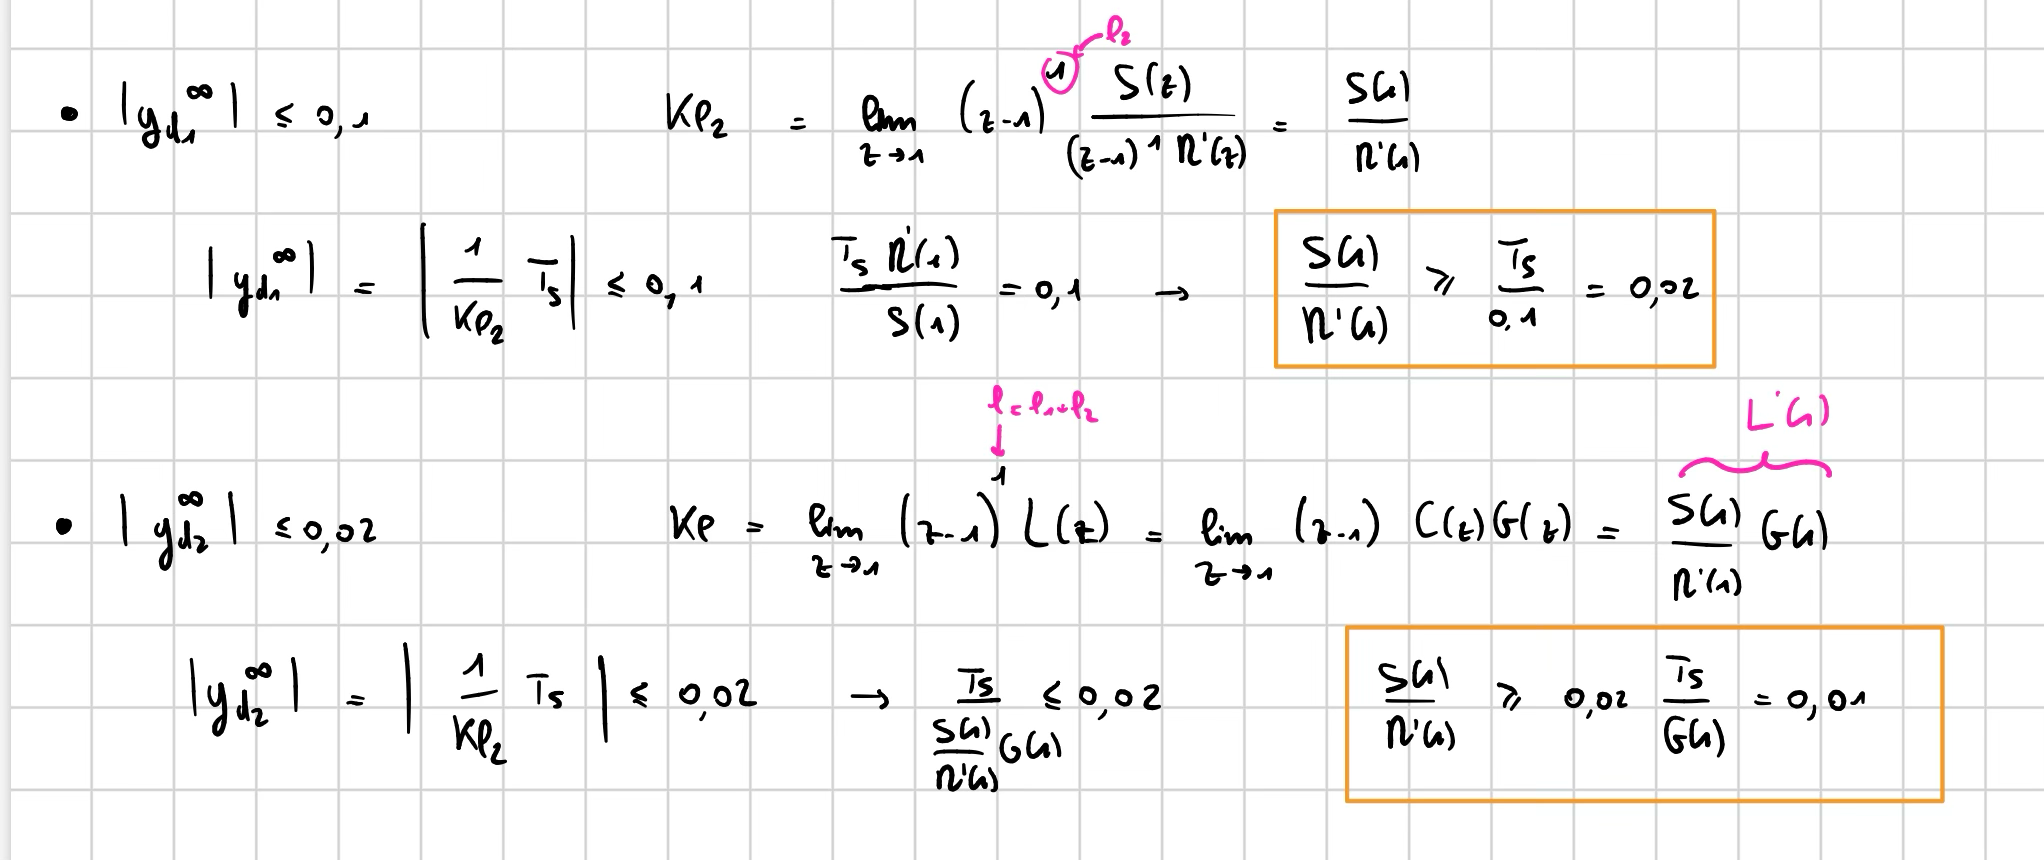

So I get an extra equation on the form S(1)/R'(1) >= 0.02

From the second requirement I get again l2 = 1 and an extra eq that is S(1)/R'(1) >= 0.01

We clearly see that the first one is more strict than the second one. **If I satisfy the first one, I know that the second one is satisfied too.**

l2 = 1;
l = l1+l2;

n_add = 1; % i need to satisfy just first equation

### Transient response

I have to compute the damping coeff according to the relation with the overshoot and wn from the relation with setting time

s_hat = 0.2; % overshoot
t_s = 0.5; % settling time
zeta = abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2); 
wn = 4.6/(zeta*t_s);  


Now I have to perform the design settings:

% figure
% pzmap(G, 'r')
% axis('equal')
% hold on
% zgrid(zeta, wn, Ts) % boh

From the pole-zero map, I can see that I can cancel just one zero (the only zero of G)

A_plus = 1;
A_minus = A; 
B_plus = [1, -zG]; % without kG because B_plus (as A_plus) MUST BE MONIC!
B_minus = kG;

% degree
deg_A = 2;
deg_A_minus = 2;
deg_A_plus = 0;
deg_B_plus = 1;
deg_B_minus = 0;

deg_S1 = l + deg_A_minus - 1 + n_add

deg_S1 = 3

deg_R2 = deg_A - deg_B_plus + l1 - 1 + n_add

deg_R2 = 1

deg_Am = l + deg_A + deg_A_minus + l1 - deg_B_plus - 1 + n_add

deg_Am = 4

C(z) will have this shape: C(z) = S(z)/(B_plus(z)*R''(z))

Since deg_Am = 4 => I need to assign 4 poles!!!

I choose a couple of complex conjugate pole that satisfy transient response formulation and 2 real and coincident poles -> 

p1c = -zeta*wn + 1j*wn*sqrt(1-zeta^2);
p1 = exp(p1c*Ts); % sampling transformation -> I get the pole value in DT
p2c = -zeta*wn - 1j*wn*sqrt(1-zeta^2);
p2 = exp(p2c*Ts); 

p3c = -5*zeta*wn; % this real pole is faster than p1 and p2
p3 = exp(p3c*Ts);

p4 = p3; % i choose the fourth pole equal to the third one 

Am = poly([p1, p2, p3, p4]);

Let's analyse now the extra eq required, from the degree of R2 and S1 I get that C will be:

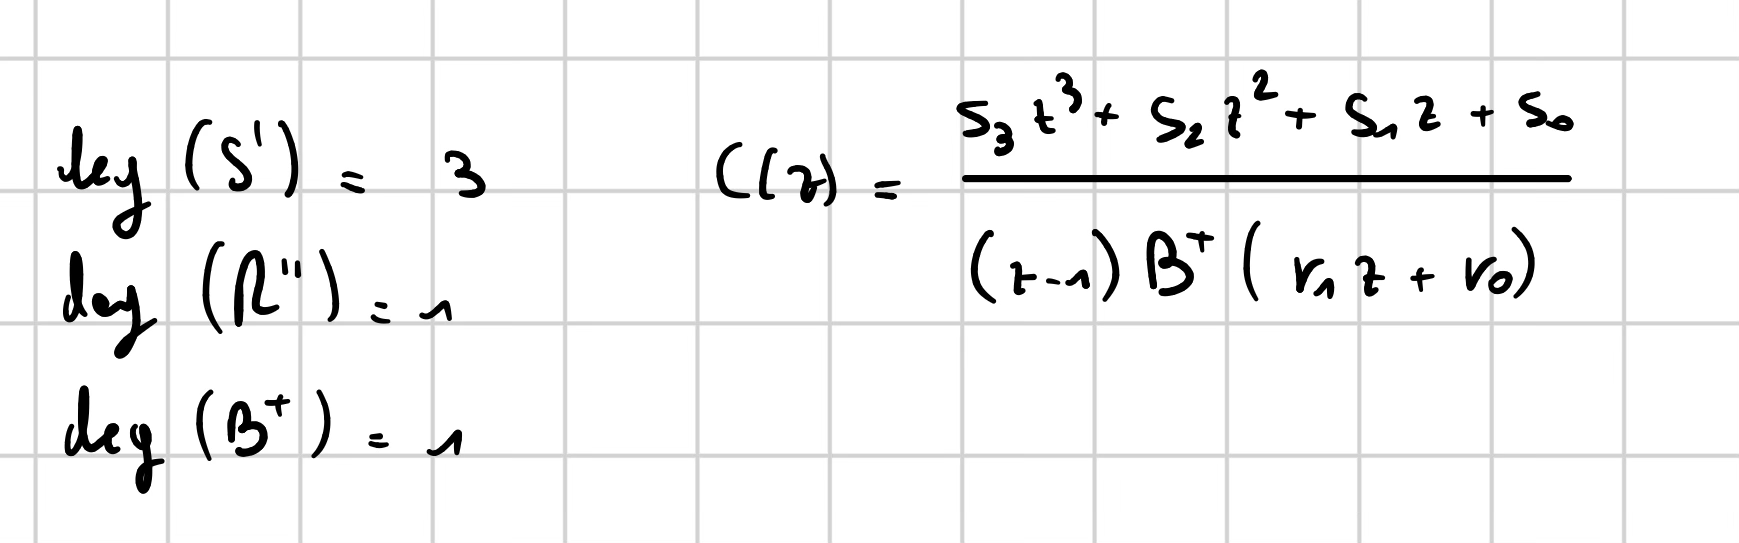

So I get

B_plus_1 = polyval(B_plus,1);
extra_eq = [-Ts/0.1*B_plus_1*ones(1,2) ones(1,4)];


Now I can solve dioph eq

A_dioph = conv([1 -1], A_minus); % remember the conv
B_dioph = B_minus;
[R2, S1, M_S] = diop_solver(A_dioph, B_dioph, Am, deg_R2, n_add, extra_eq)

R2 =     1.0000   -0.8456


S1 =     1.3983   -3.8261    3.4693   -1.0413


M_S =     1.0000         0         0         0         0         0
   -2.9996    1.0000    0.0420         0         0         0
    2.9996   -2.9996         0    0.0420         0         0
   -1.0000    2.9996         0         0    0.0420         0
         0   -1.0000         0         0         0    0.0420
   -0.0019   -0.0019    1.0000    1.0000    1.0000    1.0000


R2 = R2(:)'; %check if R2 and S1 are row vector
S1 = S1(:)';
num = conv(A_plus, S1); % REMEMBER EVERY PIECE TO BUILD THE CORRECT CONTROLLER!!!!!
den = conv([1 -1], conv(B_plus, R2));
C = zpk(tf(num, den, Ts))


C =
 
  1.3983 (z-0.77) (z^2 - 1.966z + 0.9671)
  ---------------------------------------
        (z-1) (z-0.9048) (z-0.8456)
 
Sample time: 0.002 seconds
Discrete-time zero/pole/gain model.


#### Simulation

Now we can simulate the system in order to check if all the requirements are satisfied

Tend = 2;

Let's start by verifying overshoot and setting time. In order to do this, we have to consider just a unitary step r(t) and no disturbance d1 and d2

rho = 1;
delta_1 = 0; % ignore these contributes 
delta_2 = 0; 
sim = sim("sim_with_disturbances.slx");

y = sim.y;
r = sim.r;

And now I can plot ref and output signals

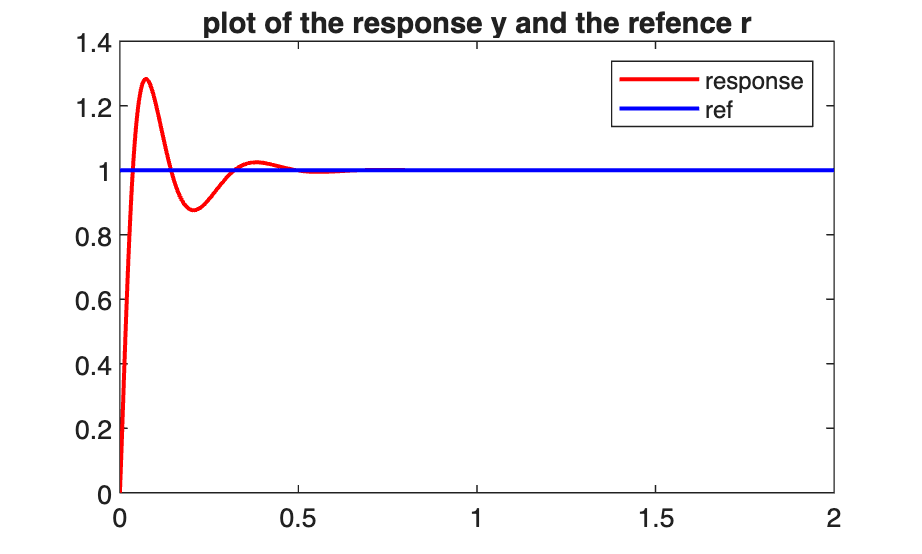

figure(1)
plot(y.time, y.data, 'r',"LineWidth",1.5)
hold on
plot(r.time, r.data, 'b', "LineWidth",1.5)
legend("response", "ref")
title("plot of the response y and the refence r")

from the simulation I get that the overshoot requirement is not satisfied, while the setting time one yes

=> I need to change the relation of the damping -> I increase the damping 

e.g. ->    zeta = abs(log(s_hat))/sqrt(pi^2+log(s_hat)^2) *** [1.15-1.2]**

Now let's verify the d1 effect on output response

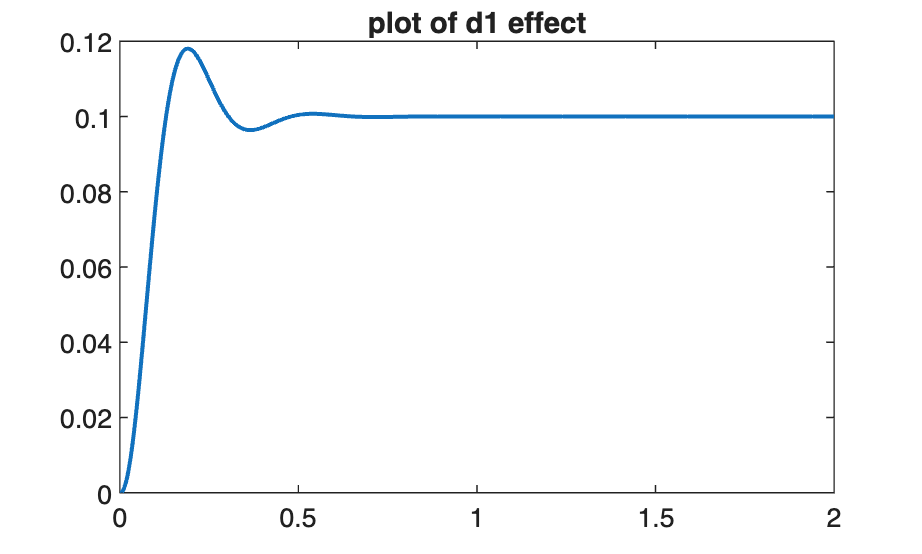

clear sim;
rho = 0;
delta_1 = 1; % just d1
delta_2 = 0; 
sim = sim("sim_with_disturbances.slx");

y = sim.y;

figure(2)
plot(y.time, y.data,"LineWidth",1.5)
title("plot of d1 effect")

fprintf("d1_inf: %g", y.data(end))

d1_inf: 0.1

fprintf("checked!")

checked!

Now let's verify the d2 effect on output response

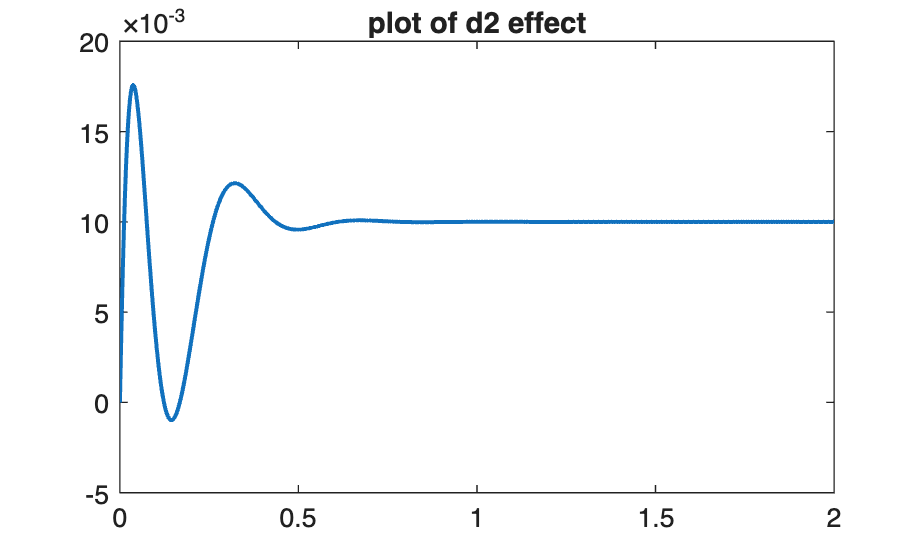

clear sim;
rho = 0;
delta_1 = 0; 
delta_2 = 1; % just d2
sim = sim("sim_with_disturbances.slx");

y = sim.y;

figure(3)
plot(y.time, y.data,"LineWidth",1.5)
title("plot of d2 effect")

fprintf("d2_inf: %g", y.data(end))

d2_inf: 0.01

fprintf("checked!")

checked!